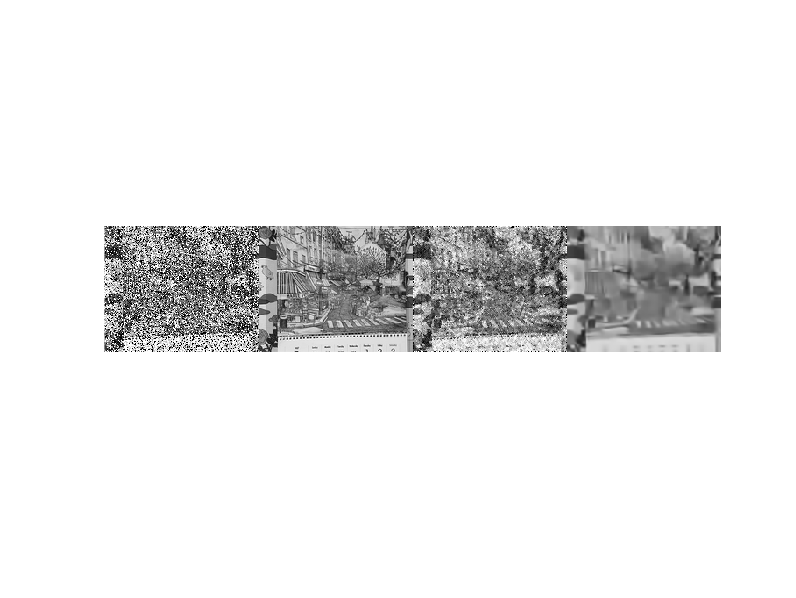

clc;
clear;
close all;

addpath("BM3D");

vid = yuv4mpeg2mov('../Test_Videos/mobile_calendar_422_qcif.y4m');

[n1,n2,~]=size(vid(1).cdata);
no_of_frames= 50; 
frame_num=20;
tau = 1.5;
iters=30;
frames= uint8(zeros([n1 n2 15]));
noisy_frames= uint8(zeros([n1 n2 no_of_frames]));
filtered_frames= uint8(zeros([n1 n2 no_of_frames]));

for i=1:no_of_frames
    frames(:,:,i)= rgb2gray(vid(i).cdata);
    noisy_frames(:,:,i) = noise(frames(:,:,i), 20, 5, 0.3);
    filtered_frames(:,:,i) = adaptive_median_filter(noisy_frames(:,:,i),10);
end

[~, Y]= VBM3D(filtered_frames,100, 0, 0); %Using the BM3D library downloaded from the internet.
Y=Y*255;

figure; imshow([noisy_frames(:,:,frame_num) frames(:,:,frame_num) filtered_frames(:,:,frame_num) Y(:,:,frame_num)])


20*log10(255*sqrt(n1*n2)/norm(double(Y(:,:,frame_num)) - double(frames(:,:,frame_num)),'fro'))

ans = 18.4981

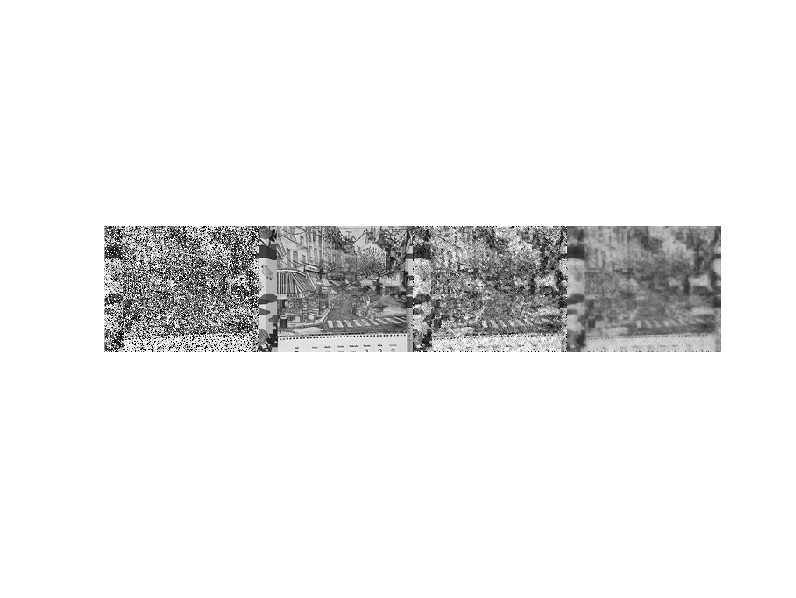


missing_pixels = (filtered_frames == noisy_frames);
patches = uint8(zeros([8*8 n1/4-1 n2/4-1 no_of_frames]));
missing = false([8*8 n1/4-1 n2/4-1 no_of_frames]);

for i=1:no_of_frames
   for j = 1:(n1/4-1)
       for k = 1:(n2/4-1)
           patches(:,j,k,i) = reshape(filtered_frames(4*(j-1)+1:4*(j-1)+8 , 4*(k-1)+1:4*(k-1)+8, i), [64 1]);
           missing(:,j,k,i) = reshape(missing_pixels(4*(j-1)+1:4*(j-1)+8 , 4*(k-1)+1:4*(k-1)+8, i), [64 1]);    
       end
   end
end

denoised_patches = double(zeros([8*8 n1/4-1 n2/4-1 no_of_frames]));
for j=1:n1/4-1
    for k=1:n2/4-1
        [patch_matrix, Omega, find]=patchmatcher(patches,j,k,frame_num,missing);
        denoised_patch = fixed_point_iteration(patch_matrix,Omega,tau,iters,find,no_of_frames);
        patches(:, j, k, frame_num) = denoised_patch;
        denoised_patches(:,j,k,frame_num) = denoised_patch;
    end
end
recon=double(zeros([n1,n2]));
count=double(zeros([n1,n2]));
for j=1:n1/4-1
        for k=1:n2/4-1
            recon(4*(j-1)+1:4*(j+1),4*(k-1)+1:4*(k+1)) =  recon(4*(j-1)+1:4*(j+1),4*(k-1)+1:4*(k+1)) + reshape(denoised_patches(:,j,k,frame_num),[8 8]);
            count(4*(j-1)+1:4*(j+1),4*(k-1)+1:4*(k+1)) = count(4*(j-1)+1:4*(j+1),4*(k-1)+1:4*(k+1)) + 1;
        end
end
recon = uint8(recon./count);
figure; 
imshow([noisy_frames(:,:,frame_num) frames(:,:,frame_num) filtered_frames(:,:,frame_num) recon]);

20*log10(255*sqrt(n1*n2)/norm(double(recon) - double(frames(:,:,frame_num)), 'fro'))

ans = 18.1712